
close all
clc

[t1, t2, t3, t4] = inv_K2(25,0,5);
l1 = 15; % height (ground to second joint)
l2 = 20; % length of first arm
l3 = 20;% length of third arm
l4 = 17.7;% length of forth arm

a0 = 0;
a1 = 0;
a2=l2;
a3=l3;

d1=l1;
d2 = 0;
d3 = 0;
d4 = 0;

alpha0 = 0;
alpha1 = pi/2;
alpha2 = 0;
alpha3 = 0;

theta1 = t1;
theta2 = t2;
theta3 = t3;
theta4 = t4;


Rx_10 = [1 0 0 0;
        0 cos(alpha0) -sin(alpha0) 0;
        0 sin(alpha0) cos(alpha0) 0;
        0 0 0 1];

Dx_10 = [1 0 0 a0;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_10 = [cos(theta1) -sin(theta1) 0 0;
        sin(theta1) cos(theta1) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_10 = [1 0 0 0;
        0 1 0 0;
        0 0 1 d1;
        0 0 0 1];

Rx_21 = [1 0 0 0;
        0 cos(alpha1) -sin(alpha1) 0;
        0 sin(alpha1) cos(alpha1) 0;
        0 0 0 1];
    
Dx_21 = [1 0 0 a1;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_21 = [cos(theta2) -sin(theta2) 0 0;
        sin(theta2) cos(theta2) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_21 = [1 0 0 0;
        0 1 0 0;
        0 0 1 d2;
        0 0 0 1];

Rx_32 = [1 0 0 0;
        0 cos(alpha2) -sin(alpha2) 0;
        0 sin(alpha2) cos(alpha2) 0;
        0 0 0 1];

Dx_32 = [1 0 0 a2;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_32 = [cos(theta3) -sin(theta3) 0 0;
        sin(theta3) cos(theta3) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_32 = [1 0 0 0;
        0 1 0 0;
        0 0 1 d3;
        0 0 0 1];

Rx_43 = [1 0 0 0;
        0 cos(alpha3) -sin(alpha3) 0;
        0 sin(alpha3) cos(alpha3) 0;
        0 0 0 1];

Dx_43 = [1 0 0 a3;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_43 = [cos(theta4) -sin(theta4) 0 0;
        sin(theta4) cos(theta4) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_43 = [1 0 0 0;
        0 1 0 0;
        0 0 1 d4;
        0 0 0 1];
    



T_10 = Rx_10 * Dx_10 * Rz_10 * Dz_10;
T_21 = Rx_21 * Dx_21 * Rz_21 * Dz_21;
T_32 = Rx_32 * Dx_32 * Rz_32 * Dz_32;
T_43 = Rx_43 * Dx_43 * Rz_43 * Dz_43;

T_40 = T_10 * T_21 * T_32 * T_43

T_40 =     0.8994   -0.4371         0   25.0000
    0.0000    0.0000   -1.0000    0.0000
    0.4371    0.8994    0.0000   22.7000
         0         0         0    1.0000


original = [0;0;0;1];
step1 = original;
step2 = T_10*original;
step3 = T_10*T_21*original;
step4 = T_10 * T_21 * T_32 * original;
step5 = T_10 * T_21 * T_32 * T_43 * original;
% step6 = T_E0* original;
graph = [step1,step2,step3,step4,step5]

graph =          0         0         0    8.0463   25.0000
         0         0         0    0.0000    0.0000
         0   15.0000   15.0000   33.3100   22.7000
    1.0000    1.0000    1.0000    1.0000    1.0000



x = step5(1)

x = 25.0000

y = step5(2)

y = 4.7149e-16

z = step5(3)

z = 22.7000

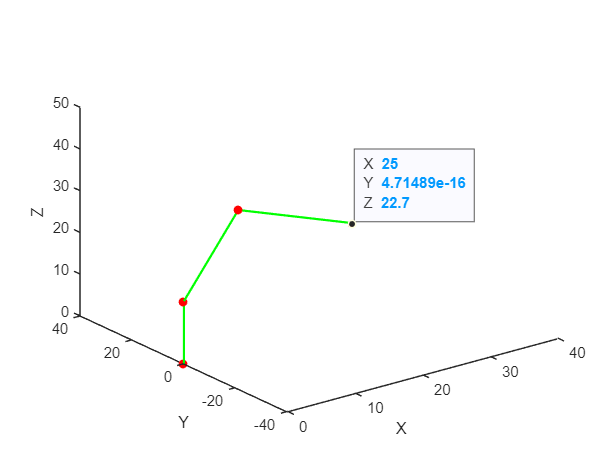


plot3(graph(1,:),graph(2,:),graph(3,:),'g','LineWidth',1.5)
hold on 
scatter3(graph(1,:),graph(2,:),graph(3,:),'red','filled')
xlabel('X')
ylabel('Y')
zlabel('Z')
xlim([0,40])
ylim([-40,40])
zlim([0,50])